# Image surface

The accommodative state of an eye is expressed in diopters (D). A given accommodation implies that points in object space, at a distance 1/D meters from the principal point of the eye, will be in optimal focus on the retina. This set of points in object space are distributed as on the surface of a sphere, and may be termed the object surface. For any given point from the object surface, we may obtain the internal focal point. The set of internal focal points that derive from the object surface form the *image surface*.

These ideas are discussed in:

- Liu, Tao, Vidhyapriya Sreenivasan, and Larry N. Thibos. "[Uniformity of accommodation across the visual field](https://jov.arvojournals.org/article.aspx?articleid=2488411)." *Journal of Vision* 16.3 (2016): 6-6.

- Verkicharla, Pavan K., et al. "Eye shape and retinal shape, and their relation to peripheral refraction." *Ophthalmic and Physiological Optics* 32.3 (2012): 184-199.

In this demonstration we will examine the image surface for an eye that is accommodated at infinity. The default eye has stigmatic but centered optical elements.

First we create the eye, imaged at 555 nm.

accommodation = 0; % Focused at infinity
eye = modelEyeParameters('spectralDomain',555,'accommodation',accommodation);

When we define visual field positions below, we will do so with respect to these reference points:

incidentNode = eye.landmarks.incidentNode.coords;
principalPoint = calcPrincipalPoint(eye);
objectDistance = 1000/accommodation; % in mm

Generate and plot the optical system:

opticalSystem = assembleOpticalSystem(eye,'surfaceSetName','mediumToRetina');
figure
plotOpticalSystem('newFigure',false,'surfaceSet',opticalSystem,'addLighting',true);
title('Image surface')
xlabel('axial [mm]'); ylabel('horizontal [mm]'); zlabel('vertical [mm]')
hold on

Add an schematic outline of the eye

plotModelEyeSchematic(eye,'newFigure',false);

Now loop over visual field positions and plot the focal points, color coded by the distance with which the focal point misses the surface of the retina

S = eye.retina.S;
eFP = []; % external focal point
iFP = []; % internal focal point
rFP = []; % error
cFP = []; % symbol plot color
for hh = -40:2.5:40
    for vv = -40:2.5:40
        if norm([hh vv])>40
            continue
        end
        [iFP(:,end+1),~,rp] = calcInternalFocalPoint(opticalSystem,[hh vv],objectDistance,incidentNode,principalPoint);
        eFP(:,end+1)=rp(:,1); % store the external focal point
        [rFP(end+1),retinaPoint] = quadric.distancePointEllipsoid(iFP(:,end),S);
        rFP(end)=rFP(end)*sign(retinaPoint(1)-iFP(1,end)); % Add a sign to the distance error
        if rFP(end) <=-0.01 % Create color codes for errors
            % Relative myopia (blue-green)
            cFP(end+1,:) = [0 min([1 -rFP(end)]) 1];
        elseif rFP(end) >= 0.01
            % relative hyperopia (red-yellow)
            cFP(end+1,:) = [1 min([1 rFP(end)]) 0];
        else
            cFP(end+1,:) = [0.5 0.5 0.5];
        end
    end
end

Add the image surface 

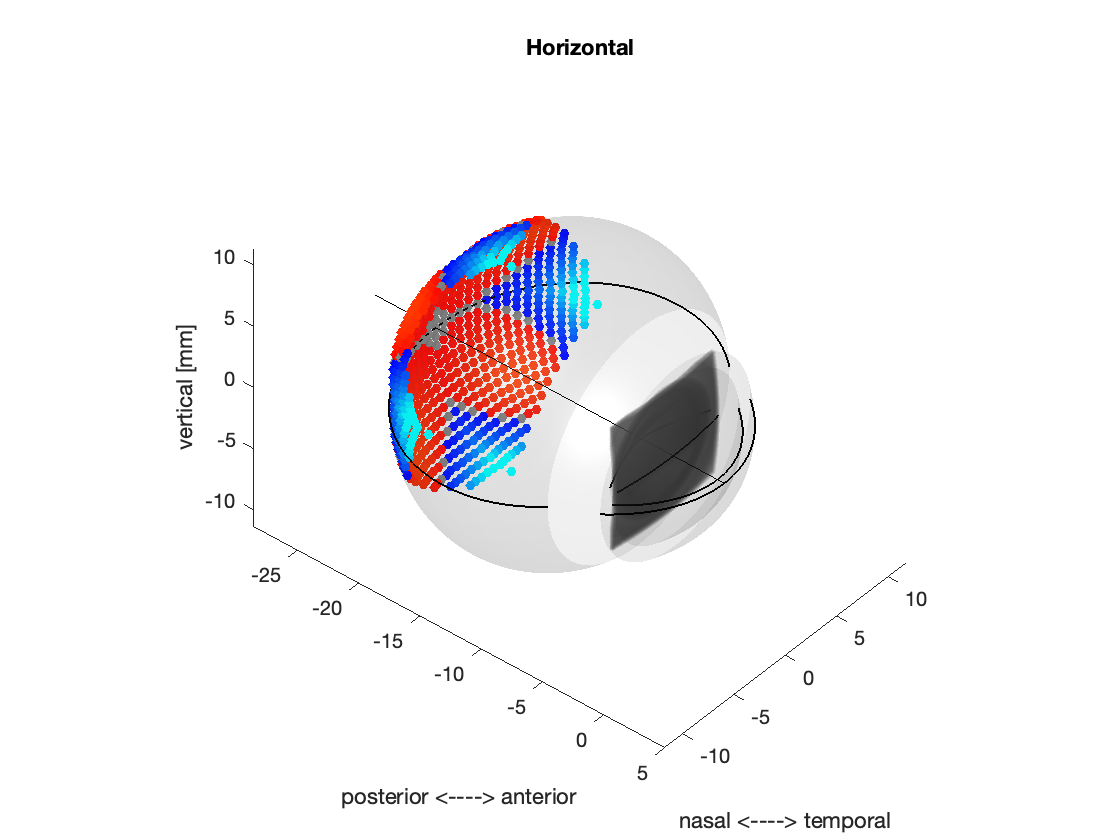

scatter3(iFP(1,:),iFP(2,:),iFP(3,:),25,cFP,'o','filled')

Color scale:

- gray: in focus (internal focal point is within 10 microns of the retinal surface)

- red --> Yellow: relative myopia

- rlue --> aqua: relative hyperopia

Plot the image and object surface

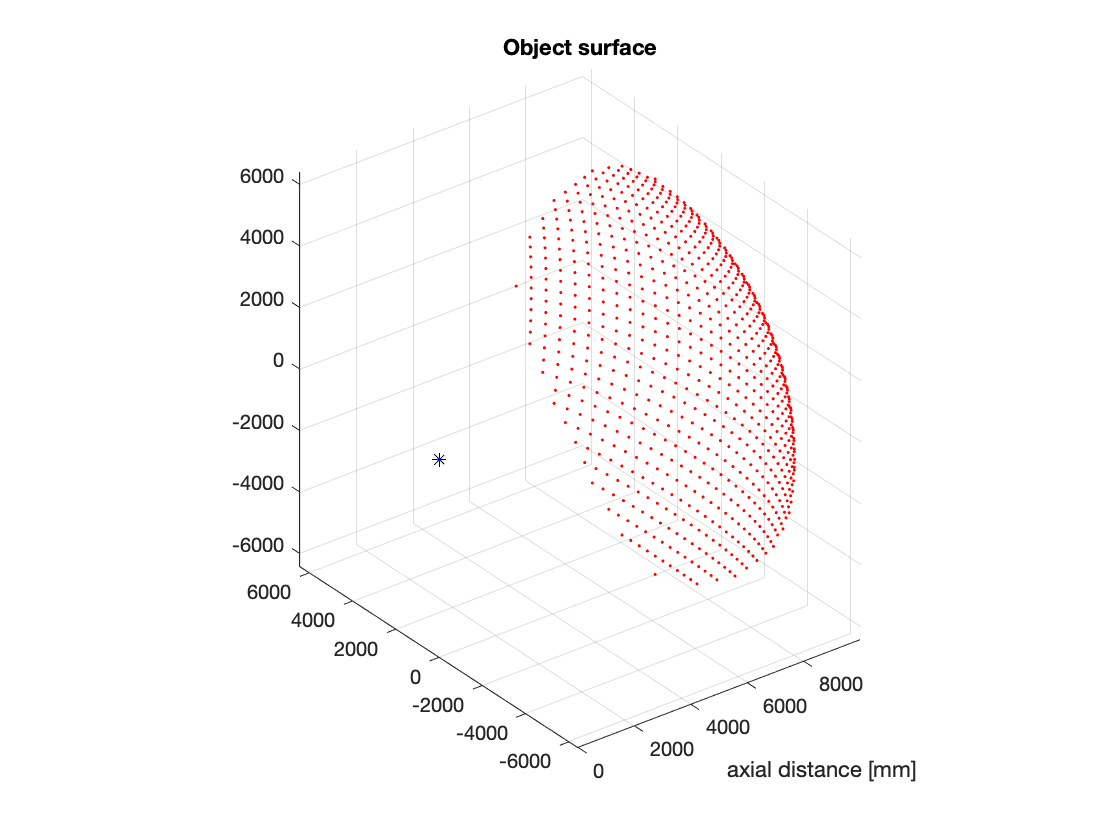

figure
scatter3(iFP(1,:),iFP(2,:),iFP(3,:),1,cFP,'.')
hold on
scatter3(eFP(1,:),eFP(2,:),eFP(3,:),1,'r','.')
plot3(principalPoint(1),principalPoint(2),principalPoint(3),'*k')
xlabel('axial distance [mm]')
title('Object surface')
xlim([-25 1000]);
axis equal

Try adjusting the accommodation parameter of the model eye and re-running the demo. You will observe that changes in the overal accommodative state of the eye have only a small effect upon the relative accommodation of the retinal periphery.